player module that uses the audioplayer object  

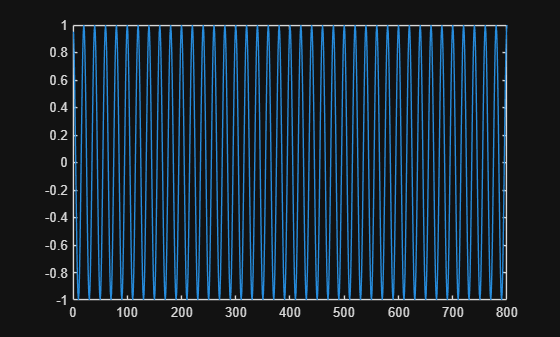

% read some parameters for generating the audio
fields = (load("data.mat"));


tau0 = fields.tau0;
tau1 = fields.tau1;
tauS = fields.tauS;

f0 = 1/tau0;
f1 = 1/tau1;

% number of bits in test signal
n=10;

% generate a test sin wave
x = [1:1:tauS*n];
test = cos(2*pi*f0 * x); 

plot(x, test)

find the correct output audio device

outDevices = audiodevinfo().output

outDevices = 1×3 struct array with fields:
    Name
    DriverVersion
    ID



% the device name is 'Speaker (Realtek(R) Audio) (Windows DirectSound)'
speakerName = 'Speakers (USB Audio Device) (Windows DirectSound)';
speakerID = 0;


% lets find the corresponding ID
for idx = [1:1:audiodevinfo(0)]
    if strcmp(outDevices(idx).Name, speakerName)
        speakerID = outDevices(idx).ID;
    end
end
speakerID

speakerID = 4

prepare the audioplayer object

% use default sample rate of audiorecorder object (8000)
Fs = 8000;
nBits = 16;
player = audioplayer(test, Fs, nBits, 4)

player =   audioplayer with properties:

       SampleRate: 8000
    BitsPerSample: 16
      NumChannels: 1
         DeviceID: 4
    CurrentSample: 1
     TotalSamples: 800
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


now use object functions to play the associated signal

playblocking(player)

also find input audio device


% TODO: add a convention for Fs and nBits
% use default sample rate of audiorecorder object for now
Fs = 8000;
nBits = 8;


%find the correct output audio device
inDevices = audiodevinfo().input

inDevices = 1×3 struct array with fields:
    Name
    DriverVersion
    ID



% the device name is 'Speaker (Realtek(R) Audio) (Windows DirectSound)'
micName = 'Microphone (USB Audio Device) (Windows DirectSound)';
micID = 1;

% lets find the corresponding ID
for idx = [1:1:audiodevinfo(1)]
    if strcmp(inDevices(idx).Name, micName)
        micID = inDevices(idx).ID;
    end
end
micID

micID = 1


%prepare the audioplayer object
recorder = audiorecorder(Fs, nBits, 1, micID)

recorder =   audiorecorder with properties:

       SampleRate: 8000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: 1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'



%now use object functions to play the associated signal
recordblocking(recorder, 5)